smoothing = 1;
    window_size = 10;   %Window size of the smoothing/moving average

calc_linearity = 1;
    windowSize = 10;    %Window size of the linearity calculator

x = 1:0.05:15;
noise_free_signal = sin(x);
% Create noise-only signal.
 noisy_signal = rand(size(noise_free_signal)); 
 % Create an amplitude for that noise that is 10% of the noise-free signal at every element.
 amplitude = .5 * noise_free_signal;
 % Now add the noise-only signal to your original noise-free signal to create a noisy signal.
 % Be sure to use .*, not *, so that you do element-by-element multiplication.
 noisy_signal = noise_free_signal + amplitude .* rand(size(noise_free_signal));
 % Adjust amplitude to control the amount of noise.

plot(noisy_signal)

data_size = length(x);

hold

Current plot held


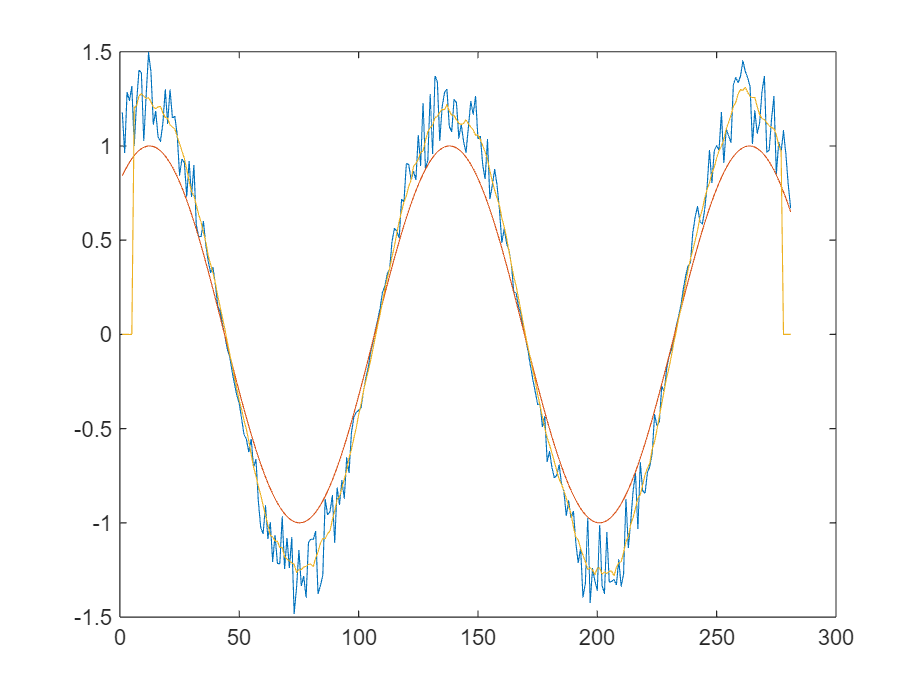

Most linear region starts at index 42


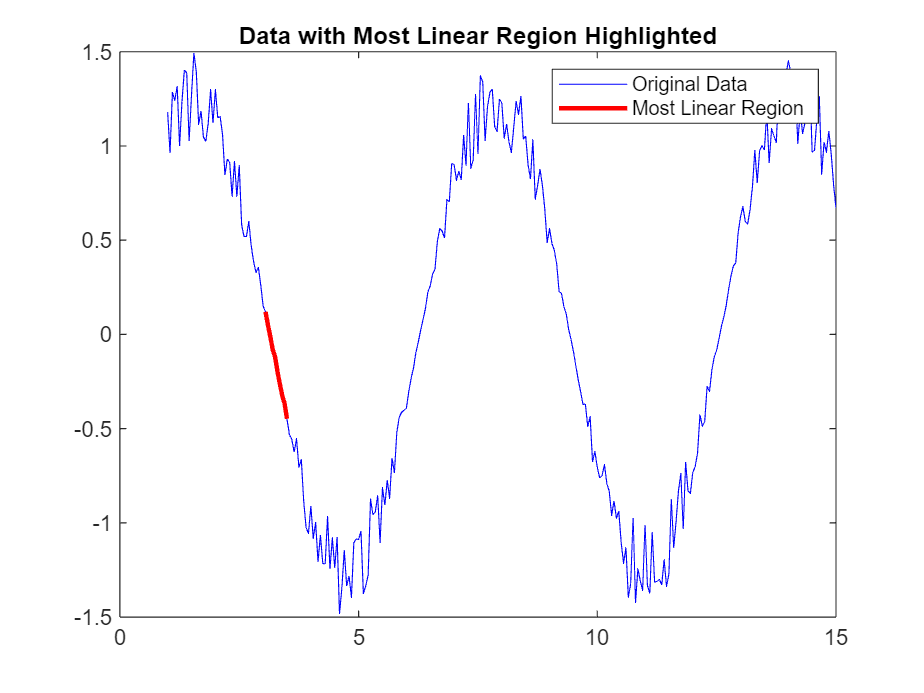

plot(noise_free_signal)

%Optionally perform smoothing of the function
if(smoothing == 1)
    % Create the filter: an array of equal weights (for a simple moving average)
    filter = ones(1, windowSize) / windowSize;
    
    % Initialize the output array
    smoothed_data = zeros(1, length(noisy_signal));
    
    % Perform the convolution (scanning the filter over the signal)
    for i = 1:(data_size - windowSize + 1)
        % Extract the window from the signal
        window = noisy_signal(i:i+windowSize-1);
        
        % Compute the dot product (mean for moving average) and store it
        smoothed_data(i + floor(windowSize/2)) = sum(window .* filter);
    end
    
    % Display the filtered signal
    plot(smoothed_data);

end



if(calc_linearity)
    hold off
    Rsq_values = zeros(1, length(x) - windowSize + 1);
    
    % Loop through the data with the sliding window
    for i = 1:(length(x) - windowSize + 1)
        % Get the current window of data
        x_window = x(i:i+windowSize-1);
        y_window = noisy_signal(i:i+windowSize-1);
        
        % Fit a line to the current window (linear regression)
        p = polyfit(x_window, y_window, 1);  % First-order polynomial (line)
        
        % Compute the fitted values for the window
        y_fit = polyval(p, x_window);
        
        % Compute the R² value (goodness of fit)
        SS_res = sum((y_window - y_fit).^2);        % Sum of squares of residuals
        SS_tot = sum((y_window - mean(y_window)).^2); % Total sum of squares
        Rsq_values(i) = 1 - SS_res/SS_tot;          % R² value
    end
    
    
    % Find the region with the highest R² value (most linear)
    [~, best_region_start] = max(Rsq_values);
    best_region_x = x(best_region_start:best_region_start+windowSize-1);
    best_region_y = noisy_signal(best_region_start:best_region_start+windowSize-1);
    
    % Display the best linear region
    fprintf('Most linear region starts at index %d\n', best_region_start);

    % Plot the data and the most linear region
    plot(x, noisy_signal, '-b');  % Original data
    hold on;
    plot(best_region_x, best_region_y, '-r', 'LineWidth', 2);  % Linear region in red
    title('Data with Most Linear Region Highlighted');
    legend('Original Data', 'Most Linear Region');
    hold off;

end